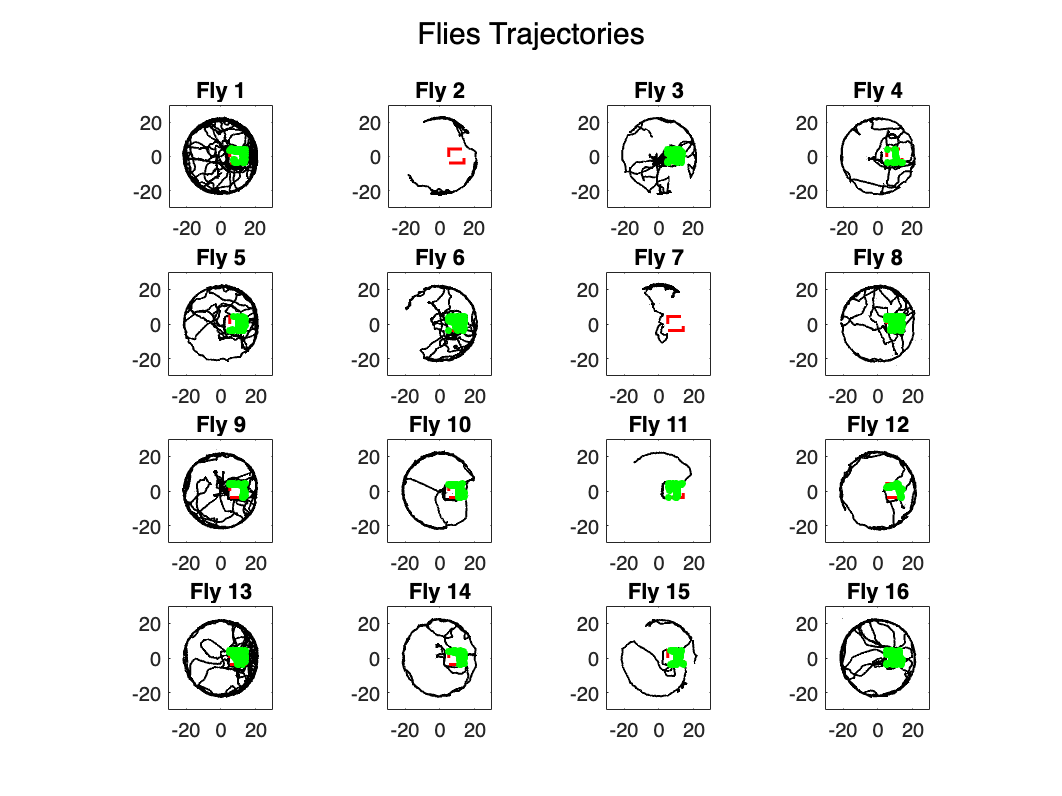

% IDs of individuals to analyze
individuals_IDs = 1:16;  

% Define the rectangular ROI (bounds)
roi_x_min = min(14.01, 5.06);  % Ensure x_min is smaller
roi_x_max = max(14.01, 5.06);  % Ensure x_max is larger
roi_y_min = min(-3.76, 4.37);  % Ensure y_min is smaller
roi_y_max = max(-3.76, 4.37);  % Ensure y_max is larger

% Initialize variable to store time spent in ROI for each fly
time_in_roi = zeros(1, length(individuals_IDs));

% Plot the trajectories with ROI marked
figure;
for i = 1:length(individuals_IDs)
    % Create a 4x4 grid for subplots
    subplot(4, 4, i);  
    
    % Access the individual's x_mm and y_mm positions
    posx = trxall(individuals_IDs(i)).x_mm;  
    posy = trxall(individuals_IDs(i)).y_mm;
    
    % Plot the trajectory
    plot(posx, posy, 'k-', 'LineWidth', 1);  
    hold on;
    
    % Plot the ROI as a red rectangle
    rectangle('Position', [roi_x_min, roi_y_min, roi_x_max - roi_x_min, roi_y_max - roi_y_min], ...
              'EdgeColor', 'r', 'LineWidth', 1.5, 'LineStyle', '--');
    
    % Highlight trajectory points inside the ROI
    in_roi = (posx >= roi_x_min & posx <= roi_x_max) & (posy >= roi_y_min & posy <= roi_y_max);
    plot(posx(in_roi), posy(in_roi), 'go', 'MarkerSize', 3, 'MarkerFaceColor', 'g');  % Green points
    
    % Calculate the time spent in the ROI
    timestamps = trxall(individuals_IDs(i)).timestamps;  % Adjust field name if needed
    if sum(in_roi) > 1  % Ensure there are at least two timestamps for diff
        time_in_roi(i) = sum(diff(timestamps(in_roi)));  % Sum durations
    else
        time_in_roi(i) = 0;  % No time spent in ROI
    end
    
    % Title for each subplot
    title(['Fly ', num2str(individuals_IDs(i))]);
    axis equal;  % Maintain aspect ratio
    xlim([-30, 30]);  % Adjust based on arena size
    ylim([-30, 30]);
    hold off;
end
sgtitle('Flies Trajectories');

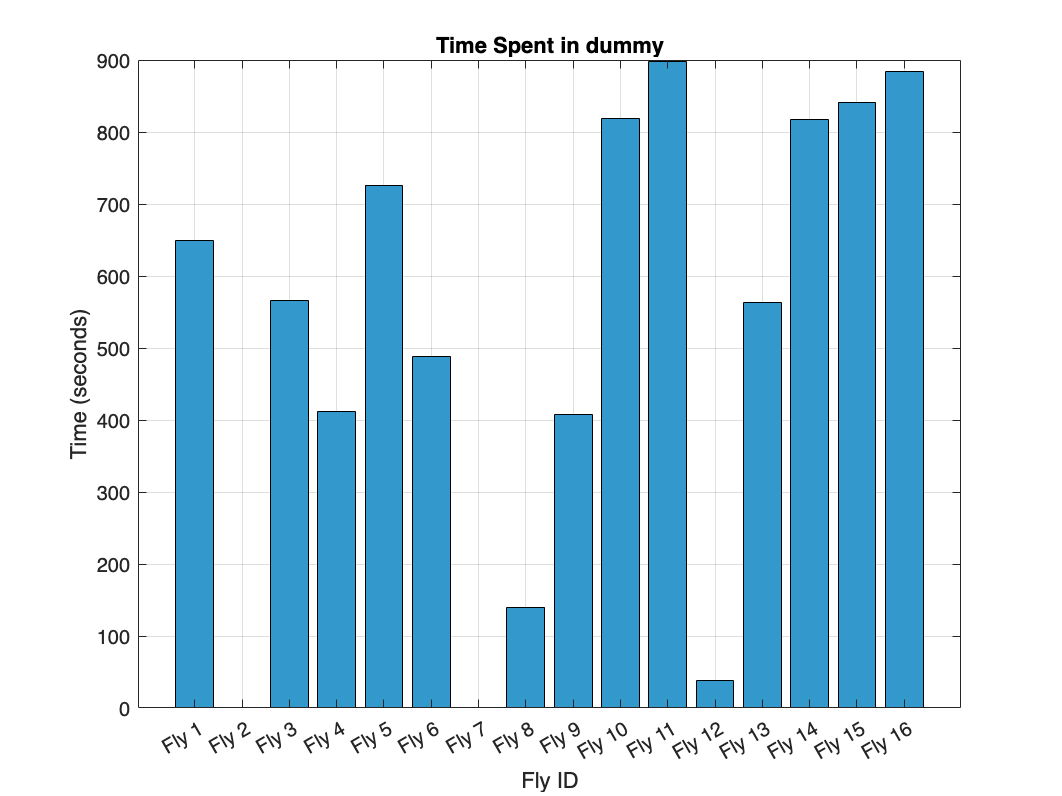


% Plot histogram of time spent in ROI
figure;
bar(time_in_roi, 'FaceColor', [0.2, 0.6, 0.8]);  % Bar plot with blue bars
xticks(1:length(individuals_IDs));
xticklabels(arrayfun(@(x) ['Fly ', num2str(x)], individuals_IDs, 'UniformOutput', false));  % Label bars with fly IDs
xlabel('Fly ID');
ylabel('Time (seconds)');
title('Time Spent in dummy');
grid on;